## Prosty tah - ukazkovy priklad z moodlu

clc, clear all, close all;
format shortG;

### Zadani

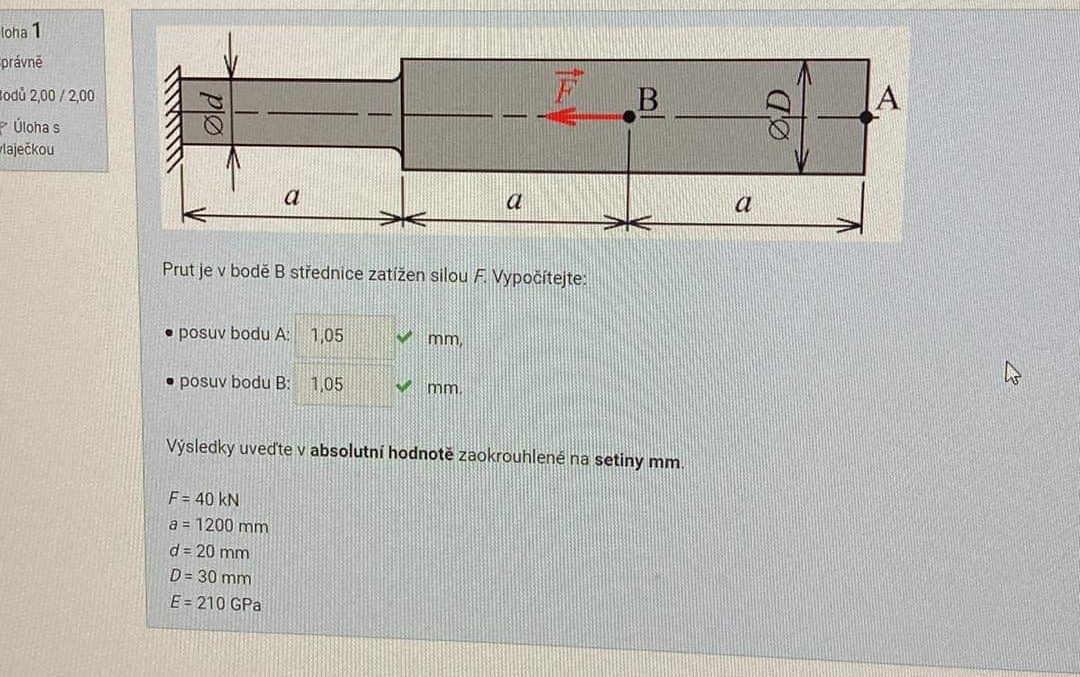

### 1. Popis prutu

#### symbolicke promenne 

syms a x
syms d D 
syms F1 F2 F3 F_dop_1 F_dop_2 % V kazdem bode sila - pridavam 2 doplnkove
syms E  

#### Numericke promenne - zadani 

% _s jako subsituce 
% 1. ZMENIT HODNOTY ZADANI, nepouzite klidne nechat idc 
a_s = 1200;
d_s = 20;
D_s = 30;
F1_s = 40000; 
F2_s = 60000;
F3_s = 60000;
F_dop_1_s = 0;
F_dop_2_s = 0;
E_s = 2.1e5;

symbolicke_promenne = [a,d,D,F1,F2,F3,F_dop_1,F_dop_2,E];
numericke_promenne = [a_s,d_s,D_s,F1_s,F2_s,F3_s,F_dop_1_s,F_dop_2_s,E_s];

#### Plochy pricnych prurezu 

S1 = (1/4)*pi*d^2;
S2 = (1/4)*pi*D^2;

#### VVU

dop. sily pusobi v kladnem smeru **x - vpravo**

% 2. Zmenit zatizeni a orientaci sil
sily = [F_dop_1,F1,F_dop_2]; % Bez orientace, v ABS hodnote
orientace_sil = [1,-1,1]; % podle VVU

normalove = construct_VVU_N(sily,orientace_sil);

#### Rozlozeni casti prutu

kazdy zacina volnym koncem, postupuje smerem k vetknuti, vsechny 3 vektory musi byt stejne dlouhe

% 3. Zmenit delky useku a jejich prurezy
% Vsechny orientovat stejne, jinac to nebude fungovat
useky = [a,a,a]; % odpovidaji usekum VVU
prurezy = [S1,S1,S2];

### 2. Vypocet

#### Potencialni energie napjatosti prutu 


$$W = \int_0^a \frac{N_1^2}{2ES}dx + \int_0^a \frac{N_2^2}{2ES}dx + 
\int_0^a \frac{N_3^2}{2ES}dx +
\int_0^a \frac{N_4^2}{2ES}dx  + ......$$


skripta strana 102

dW = energie_useku(normalove,E,prurezy);
W = celk_energie(dW,useky,x);

#### POSUVY bodu - Parcialni derivace podle jednotlivych sil 

dW_F = diff_sym_posuv(W,sily);

#### Posuvy v A,B,C,D vycislene

posuvy = vycisleni_posuvu(dW_F,symbolicke_promenne,numericke_promenne)

posuvy =       -1.0509       1.0509     -0.32336


posuvy_zaokrouhlene = abs(round(posuvy,2)) % toto dela i ABS hodnotu

posuvy_zaokrouhlene =          1.05         1.05         0.32


celkova_zmena = round(sum(posuvy),2) 

celkova_zmena =         -0.32


function energie_telesa_W = celk_energie(A,useky,d_something)        
    zintegrovane = arrayfun(@(dW,a) int(dW,d_something,0,a),A,useky);
    energie_telesa_W = sum(zintegrovane);
end

function vektor_napjatosti = energie_useku(N,E,prurezy)
    vektor_napjatosti = arrayfun(@(N,S) dW_useku(N,E,S),N,prurezy);   
end

function dW = dW_useku(N,E,S)
    dW = (N^2)/(2*E*S);
end

function posuvy_symbolicky = diff_sym_posuv(W,sily)
    posuvy_symbolicky = arrayfun(@(F) diff(W,F),sily);
end

function posuvy_numericky = vycisleni_posuvu(dW_F,sym,num)
%     posuvy_sym_ciselne = arrayfun(@(dW,s,n) subs(dW,s,n),dW_F,sym,num);
%     posuvy_numericky = double(posuvy_sym_ciselne); DUNNO, NEFUNGUJE TO 
    posuvy_numericky = zeros(size(dW_F));
    for i=1:length(dW_F)
        posuvy_numericky(i) = double(subs(dW_F(i),sym,num));
    end

end

function normalove = construct_VVU_N(sily,orientace)
    orientovane_sily = sily.*orientace;
    normalove = sym(zeros(size(sily)));
    for i=1:length(sily)
        normalove(i) = sum(orientovane_sily(1:i));
    end
end